clear all;
clc;

# Adaptive filtering

### Data construction

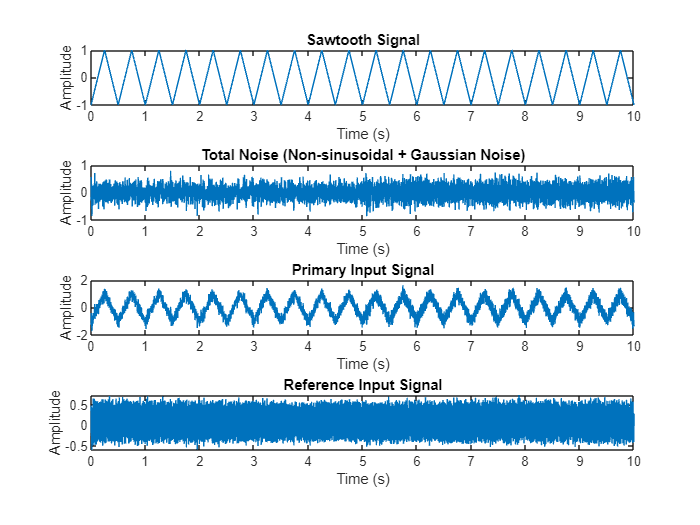

Fs = 500;   % Sampling frequency
N = 5000;   % Number of samples

t = linspace(0, 10, N)';    % Time vector

phi = pi/8;
s = sawtooth(2 * pi * 2 * t(1:N,1), 0.5); % Sawtooth signal
n1 = 0.2 * sin(2 * pi * 50 * t(1:N/2,1) - phi);     % 50Hz sinusoidal   
n2 = 0.3 * sin(2 * pi * 100 * t(N/2+1:N,1) - phi);   % 100Hz sinusoidal
noise_non_s = [n1 ; n2];

snr = 10;
rng(0);
nwg = s - awgn(s, snr, "measured"); % Gaussian white noise

total_noise = noise_non_s + nwg;    % Total noise

input_primary = s + total_noise;    % primary input signal

% Construct the reference signal
a = 0.3;
phi_1 = pi/4;
phi_2 = pi/6;

input_reference = a * (nwg + sin(2 * pi * 50 * t + phi_1) + sin(2 * pi * 100 * t + phi_2));

% Plotting the signals one by one
figure;

subplot(4,1,1);
plot(t, s);
title('Sawtooth Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, total_noise);
title('Total Noise (Non-sinusoidal + Gaussian Noise)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, input_primary);
title('Primary Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, input_reference);
title('Reference Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

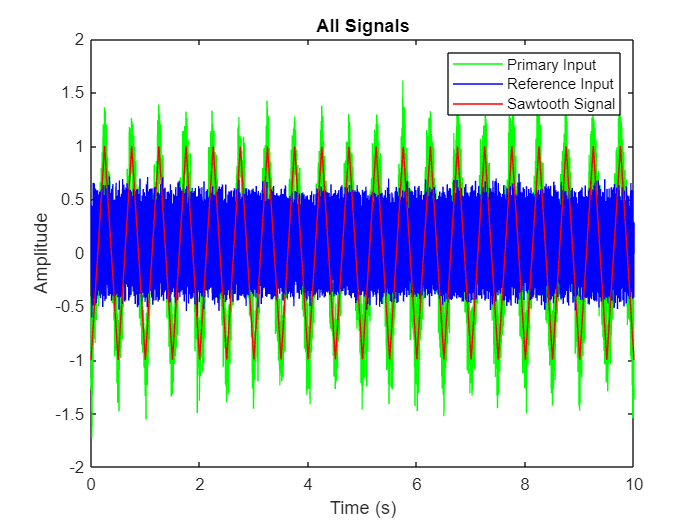



% Plotting all the signals in one figure
figure;
plot(t, input_primary, 'g', t, input_reference, 'b', t, s, 'r');
title('All Signals');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Primary Input', 'Reference Input', 'Sawtooth Signal');

### 2.1 LMS method

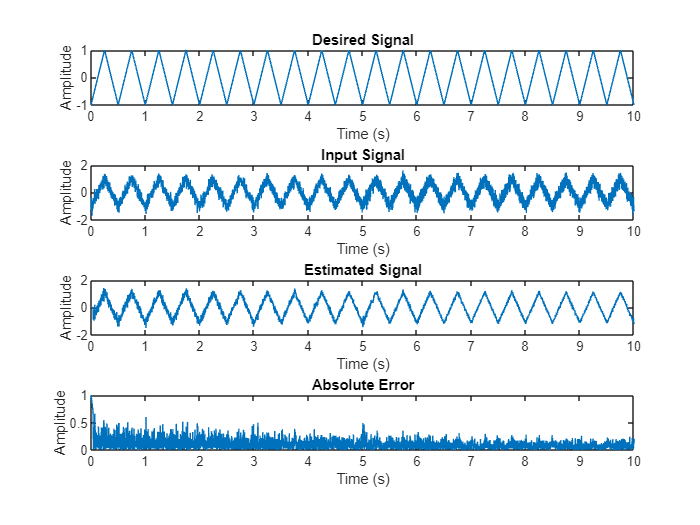

LMSOrder = 20;
mu_max = LMS_rate_of_conv(input_reference, LMSOrder);
[LMS_error, LMS_estimated, LMS_w_i] = Least_Mean_Square(input_primary, input_reference, LMSOrder, mu_max);

% Plotting the signals one by one
figure;

subplot(4,1,1);
plot(t, s);
title('Desired Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, input_primary);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, LMS_estimated);
title('Estimated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs(s - LMS_estimated));
title('Absolute Error');
xlabel('Time (s)');
ylabel('Amplitude');

disp(mean((s-LMS_estimated).^2));

    0.0199



Max_LMS_Order = 20;
LMS_Orders = 1 : 1 : Max_LMS_Order;

Max_mu = mu_max;
LMS_mus = linspace(0, Max_mu, 20);

LMS_MSEs = zeros(length(LMS_Orders), length(LMS_mus));
for i = 1 : length(LMS_Orders)
    for j = 1 : length(LMS_mus)
        [LMS_error, LMS_estimated_i, LMS_w_i] = Least_Mean_Square(input_primary, input_reference, LMS_Orders(i), LMS_mus(j));

        % Calculate the MSE and store it
        LMS_MSEs(i, j) = mean((s - LMS_estimated_i).^2);
    end
end

% Plotting the LMS MSEs
figure;
surf(LMS_Orders, LMS_mus, LMS_MSEs');
xlabel('LMS Order');
ylabel('LMS Step Size (\mu)');
zlabel('Mean Squared Error (MSE)');
title('LMS MSEs for Different Orders and Step Sizes');
colorbar;

% Set the view direction (azimuth and elevation)
view(-75, 10);  

% Finding the minimum value and its corresponding indices
[min_MSE, idx] = min(LMS_MSEs(:));
[i_min, j_min] = ind2sub(size(LMS_MSEs), idx);

opt_LMS_Order = LMS_Orders(i_min);
opt_LMS_mu = LMS_mus(j_min);


% Display the minimum value and the corresponding parameters
disp(['Minimum MSE: ', num2str(min_MSE)]);

Minimum MSE: 0.018048


disp(['LMS Order: ', num2str(LMS_Orders(i_min))]);

LMS Order: 10


disp(['LMS Step Size (\mu): ', num2str(LMS_mus(j_min))]);

LMS Step Size (\mu): 0.053456


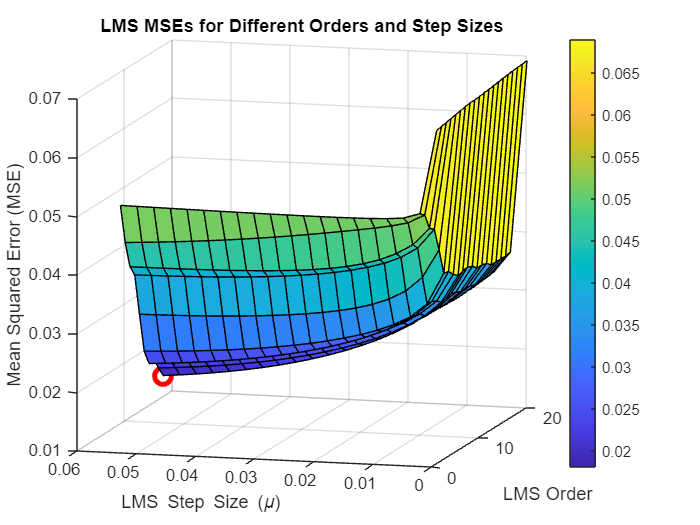


% Highlight the point of minimum MSE on the plot
hold on;
plot3(LMS_Orders(i_min), LMS_mus(j_min), min_MSE, 'ro', 'MarkerSize', 10, 'LineWidth', 3);
hold off;

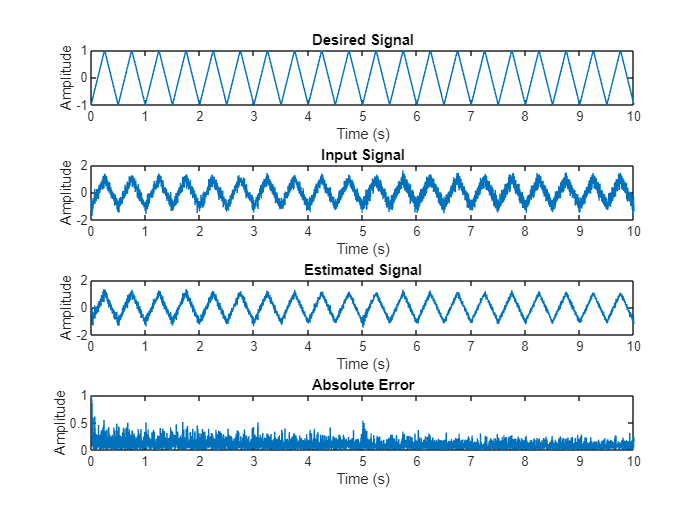

% Optimum filter
[LMS_error_opt, LMS_estimated_opt, LMS_w_i_opt] = Least_Mean_Square(input_primary, input_reference, opt_LMS_Order, opt_LMS_mu);

% Plotting the optimum filtered signal
figure;

subplot(4,1,1);
plot(t, s);
title('Desired Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, input_primary);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, LMS_estimated_opt);
title('Estimated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs(s - LMS_estimated_opt));
title('Absolute Error');
xlabel('Time (s)');
ylabel('Amplitude');

### 2.2 RLS method

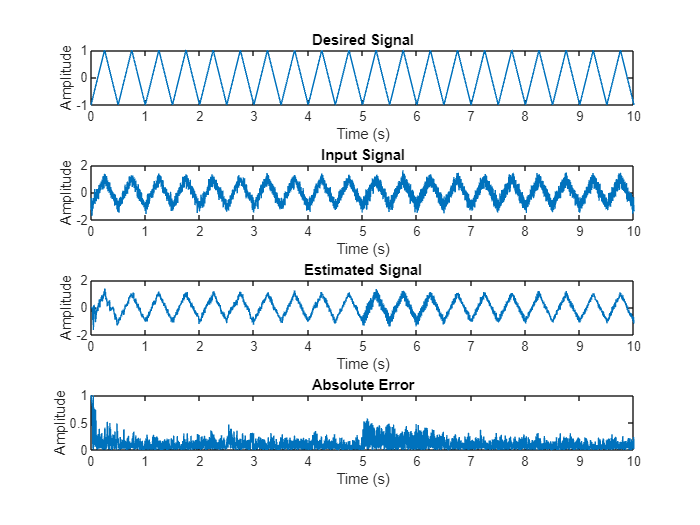

RLSOrder = 15;
[RLS_error, RLS_estimated, RLS_w_i] = Recursive_Least_Squares(input_primary, input_reference, RLSOrder, 0.999);

% Plotting the signals one by one
figure;

subplot(4,1,1);
plot(t, s);
title('Desired Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, input_primary);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, RLS_estimated);
title('Estimated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs(s - RLS_estimated));
title('Absolute Error');
xlabel('Time (s)');
ylabel('Amplitude');

disp(mean((s-RLS_estimated).^2));

    0.0214



Max_RLS_Order = 40;
RLS_Orders = 1 : 1 : Max_RLS_Order;

Max_lambda = 1;
RLS_lambdas = linspace(0, Max_lambda, 20);

RLS_MSEs = zeros(length(RLS_Orders), length(RLS_lambdas));
for i = 1 : length(RLS_Orders)
    for j = 1 : length(RLS_lambdas)
        [RLS_error, RLS_estimated_i, RLS_w_i] = Recursive_Least_Squares(input_primary, input_reference, RLS_Orders(i), RLS_lambdas(j));

        % Calculate the MSE and store it
        RLS_MSEs(i, j) = mean((s - RLS_estimated_i).^2);
    end
end


% Plotting the RLS MSEs
figure;
surf(RLS_Orders, RLS_lambdas, RLS_MSEs');
xlabel('RLS Order');
ylabel('RLS Step Size');
zlabel('Mean Squared Error (MSE)');
title('RLS MSEs for Different Orders and lambdas');
colorbar;

 

% Finding the minimum value and its corresponding indices
[min_MSE_1, idx_1] = min(RLS_MSEs(:));
[i_min, j_min] = ind2sub(size(RLS_MSEs), idx_1);

opt_RLS_Order = RLS_Orders(i_min);
opt_RLS_lambda = RLS_lambdas(j_min);


% Display the minimum value and the corresponding parameters
disp(['Minimum MSE: ', num2str(min_MSE_1)]);

Minimum MSE: 0.029491


disp(['RLS Order: ', num2str(RLS_Orders(i_min))]);

RLS Order: 24


disp(['RLS Step Size (lambda): ', num2str(RLS_lambdas(j_min))]);

RLS Step Size (lambda): 1


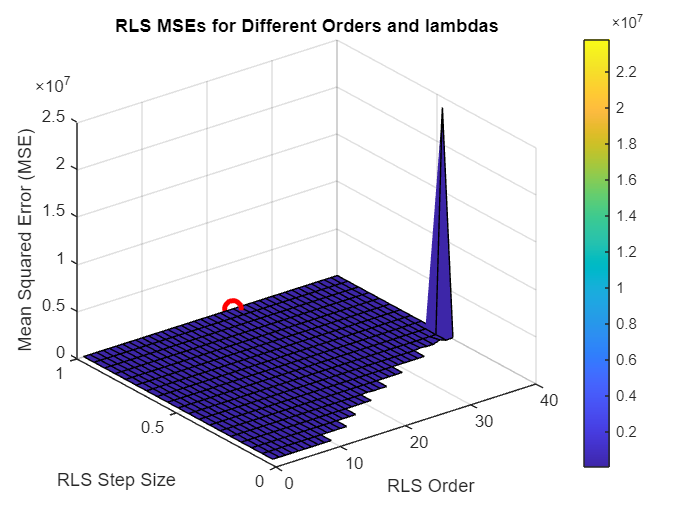


% Highlight the point of minimum MSE on the plot
hold on;
plot3(RLS_Orders(i_min), RLS_lambdas(j_min), min_MSE_1, 'ro', 'MarkerSize', 10, 'LineWidth', 3);
hold off;

Max_RLS_Order = 40;
RLS_Orders = 1 : 1 : Max_RLS_Order;

Max_lambda = 0.9999;
RLS_lambdas = linspace(0.99, Max_lambda, 20);

RLS_MSEs = zeros(length(RLS_Orders), length(RLS_lambdas));
for i = 1 : length(RLS_Orders)
    for j = 1 : length(RLS_lambdas)
        [RLS_error, RLS_estimated_i, RLS_w_i] = Recursive_Least_Squares(input_primary, input_reference, RLS_Orders(i), RLS_lambdas(j));

        % Calculate the MSE and store it
        RLS_MSEs(i, j) = mean((s - RLS_estimated_i).^2);
    end
end

% Plotting the RLS MSEs
figure;
surf(RLS_Orders, RLS_lambdas, RLS_MSEs');
xlabel('RLS Order');
ylabel('RLS Step Size');
zlabel('Mean Squared Error (MSE)');
title('RLS MSEs for Different Orders and lambdas');
colorbar;

 % Set the view direction (azimuth and elevation)
view(-30, 30); 

% Finding the minimum value and its corresponding indices
[min_MSE_1, idx_1] = min(RLS_MSEs(:));
[i_min, j_min] = ind2sub(size(RLS_MSEs), idx_1);

opt_RLS_Order = RLS_Orders(i_min);
opt_RLS_lambda = RLS_lambdas(j_min);


% Display the minimum value and the corresponding parameters
disp(['Minimum MSE: ', num2str(min_MSE_1)]);

Minimum MSE: 0.018765


disp(['RLS Order: ', num2str(RLS_Orders(i_min))]);

RLS Order: 21


disp(['RLS Step Size (lambda): ', num2str(RLS_lambdas(j_min))]);

RLS Step Size (lambda): 0.99834


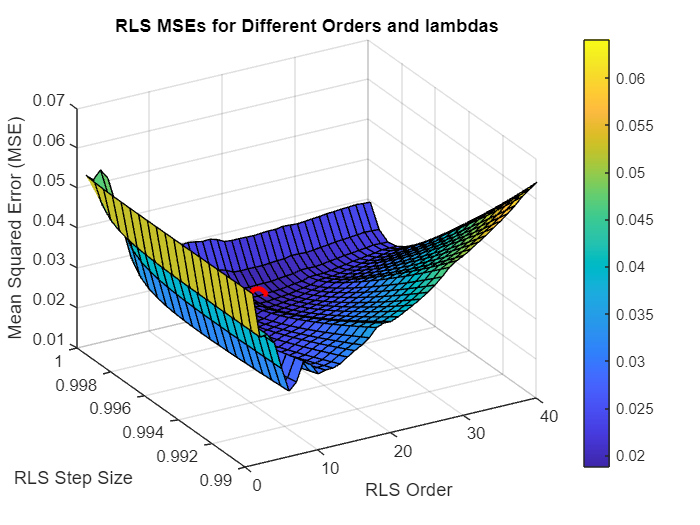


% Highlight the point of minimum MSE on the plot
hold on;
plot3(RLS_Orders(i_min), RLS_lambdas(j_min), min_MSE_1, 'ro', 'MarkerSize', 10, 'LineWidth', 3);
hold off;

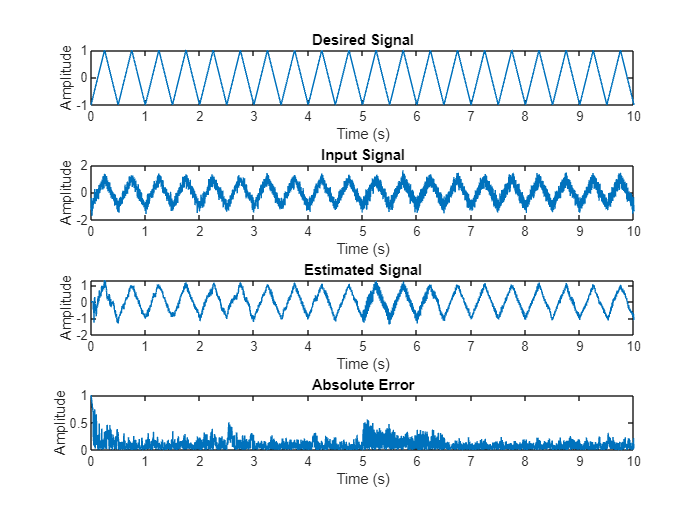

% Optimum filter
[RLS_error_opt, RLS_estimated_opt, RLS_w_i_opt] = Recursive_Least_Squares(input_primary, input_reference, opt_RLS_Order, opt_RLS_lambda);

% Plotting the optimum filtered signal
figure;

subplot(4,1,1);
plot(t, s);
title('Desired Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, input_primary);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, RLS_estimated_opt);
title('Estimated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs(s - RLS_estimated_opt));
title('Absolute Error');
xlabel('Time (s)');
ylabel('Amplitude');

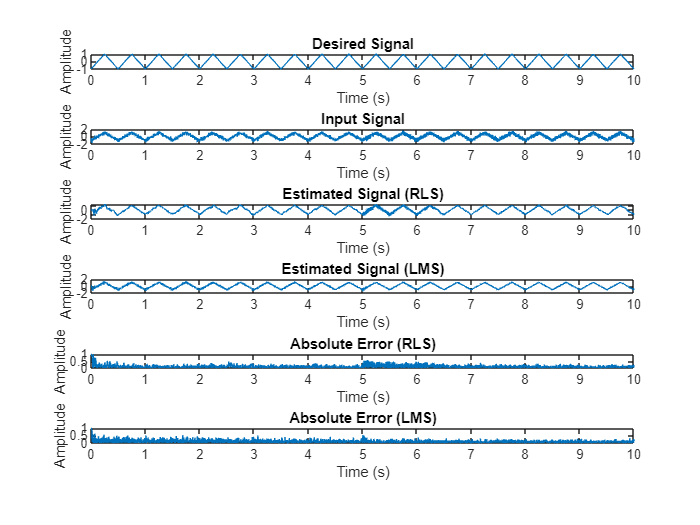

% Comparison of LMS and RLS algorithms
% Plotting the optimum filtered signal
figure;

subplot(6,1,1);
plot(t, s);
title('Desired Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(6,1,2);
plot(t, input_primary);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(6,1,3);
plot(t, RLS_estimated_opt);
title('Estimated Signal (RLS)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(6,1,4);
plot(t, LMS_estimated_opt);
title('Estimated Signal (LMS)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(6,1,5);
plot(t, abs(s - RLS_estimated));
title('Absolute Error (RLS)');
xlabel('Time (s)');
ylabel('Amplitude');


subplot(6,1,6);
plot(t, abs(s - LMS_estimated_opt));
title('Absolute Error (LMS)');
xlabel('Time (s)');
ylabel('Amplitude');

### Test algorithms using ECG waveform

data = load("idealECG.mat");

disp(fieldnames(data));

    {'idealECG'}



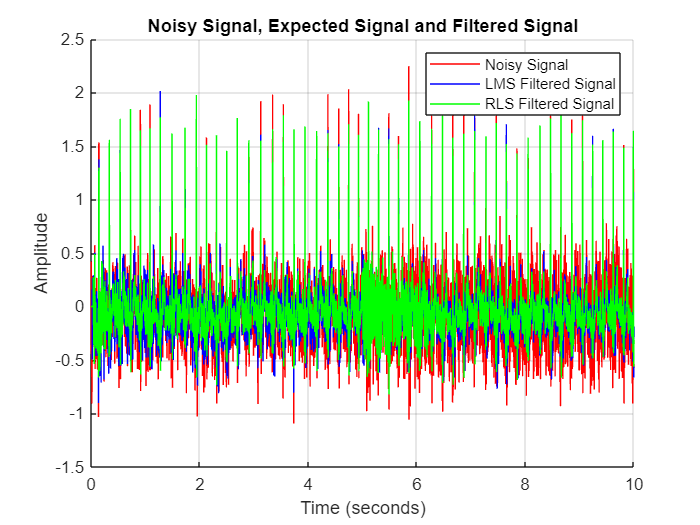


% y_i is the ideal signal
y_i = data.idealECG; 

ecg_primary = y_i(1:5000)' + total_noise;
ecg_reference = input_reference;

% Apply Optimum LMS filter
[LMS_error_ecg, LMS_estimated_ecg, LMS_w_i_ecg] = Least_Mean_Square(ecg_primary, ecg_reference, opt_LMS_Order, opt_LMS_mu);

% Apply Optimum RLS filter
[RLS_error_ecg, RLS_estimated_ecg, RLS_w_i_ecg] = Recursive_Least_Squares(ecg_primary, ecg_reference, opt_RLS_Order, opt_RLS_lambda);


% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(t, ecg_primary, 'r-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(t, LMS_estimated_ecg, 'b-', 'DisplayName', 'LMS Filtered Signal');  % Filtered signal in solid blue line
plot(t, RLS_estimated_ecg, 'g-', 'DisplayName', 'RLS Filtered Signal')
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

t__ = 1:250

t__ =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


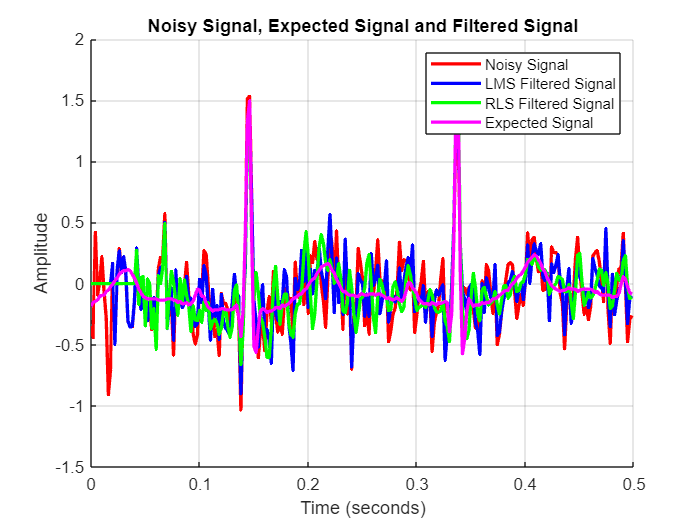

% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(t(t__), ecg_primary(t__), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(t(t__), LMS_estimated_ecg(t__), 'b-', 'DisplayName', 'LMS Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(t(t__), RLS_estimated_ecg(t__), 'g-', 'DisplayName', 'RLS Filtered Signal', 'LineWidth', 2)
plot(t(t__), y_i(t__), 'm-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot